# GradCam

#### Fred liu 2022.5.20

**載入模型與影像(Load Model & Image)**

net = resnet50;
img = imread("t01.jpg");

**影像辨識(Image Classify)**

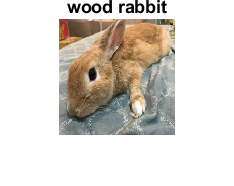

inputSize = net.Layers(1).InputSize(1:2);
re_img = imresize(img,inputSize);
figure,imshow(re_img)

[label,scores] = classify(net,re_img);
title(char(label))

**影像可視化(Image Occlusion)**

map = gradCAM(net,re_img,label);

**顯示熱圖(Show ScoreMap)**

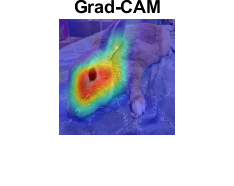

figure,imshow(re_img);
hold on;
imagesc(map,'AlphaData',0.5);
colormap jet
hold off;
title("Grad-CAM");

**顯示某一層的GardCam(Shallow Layer)**

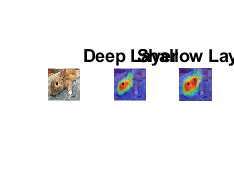

gradcamMapShallow = gradCAM(net,re_img,label,'FeatureLayer',"res5c_branch2c");

figure
alpha = 0.5;
cmap = "jet";
plotMaps(re_img,map,gradcamMapShallow,"Deep Layer","Shallow Layer",alpha,cmap)

function plotMaps(img,map1,map2,title1,title2,alpha,cmap)

figure
subplot(1,3,1)
imshow(img)

subplot(1,3,2)
imshow(img)
hold on
imagesc(map1,'AlphaData',alpha)
colormap(cmap)
title(title1)
hold off

subplot(1,3,3)
imshow(img)
hold on
imagesc(map2,'AlphaData',alpha)
colormap(cmap)
title(title2)
hold off
end